# Robotics, Vision & Control 3e: for MATLAB

# Chapter 2: Representing position & orientation

Copyright 2022-2023 Peter Corke, Witold Jachimczyk, Remo Pillat

close all  % close all existing figures

## 2.2 Working in Two Dimensions (2D)

### 2.2.1 Orientation in Two Dimensions

#### 2.2.1.1 2D Rotation Matrix

R = rotm2d(0.3)

R =     0.9553   -0.2955
    0.2955    0.9553


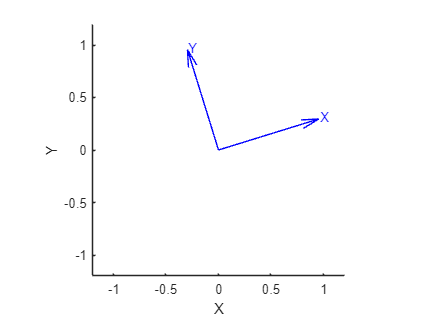

plottform2d(R);

det(R)

ans = 1.0000

det(R*R)

ans = 1.0000

syms theta real
R = rotm2d(theta)

$$R = \left(\begin{array}{cc} \cos\left(\theta \right) & -\sin\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

simplify(R * R)

$$ans = \left(\begin{array}{cc} \cos\left(2\,\theta \right) & -\sin\left(2\,\theta \right)\\ \sin\left(2\,\theta \right) & \cos\left(2\,\theta \right) \end{array}\right)$$

det(R)

$$ans = {\cos\left(\theta \right)}^{2}+{\sin\left(\theta \right)}^{2}$$

simplify(ans) 

$$ans = 1$$

#### 2.2.1.2 Matrix Exponential for Rotation

R = rotm2d(0.3);
L = logm(R)

L =          0   -0.3000
    0.3000         0


S = skew2vec(L)

S = 0.3000

X = vec2skew(2)

X =      0    -2
     2     0


skew2vec(X)

ans = 2

expm(L)

ans =     0.9553   -0.2955
    0.2955    0.9553


expm(vec2skew(S))

ans =     0.9553   -0.2955
    0.2955    0.9553


### 2.2.2 Pose in Two Dimensions

#### 2.2.2.1 2D Homogeneous Transformation Matrix

rotm2d(0.3)

ans =     0.9553   -0.2955
    0.2955    0.9553


tformr2d(0.3)

ans =     0.9553   -0.2955         0
    0.2955    0.9553         0
         0         0    1.0000


TA = trvec2tform([1 2])*tformr2d(deg2rad(30))

TA =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000


clf; axis([0 5 0 5]); hold on % new plot with both axes from 0 to 5
plottform2d(TA,frame="A",color="b");
T0 = trvec2tform([0 0]);
plottform2d(T0, frame="0",color="k");  % reference frame
TB = trvec2tform([2 1])

TB =      1     0     2
     0     1     1
     0     0     1


plottform2d(TB,frame="B",color="r");
TAB = TA*TB

TAB =     0.8660   -0.5000    2.2321
    0.5000    0.8660    3.8660
         0         0    1.0000


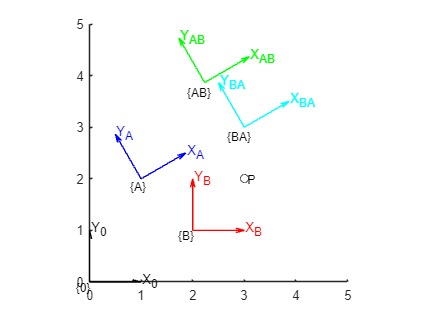

plottform2d(TAB,frame="AB",color="g");
TBA = TB*TA;
plottform2d(TBA,frame="BA",color="c");
P = [3;2];  % column vector
plotpoint(P',"ko",label="P");

inv(TA)*[P;1]

ans =     1.7321
   -1.0000
    1.0000


h2e(ans')

ans =     1.7321   -1.0000


homtrans(inv(TA),P')

ans =     1.7321   -1.0000


#### 2.2.2.2 Rotating a Coordinate Frame

clf; axis([-5 4 -1 5]);
T0 = trvec2tform([0 0]);
plottform2d(T0,frame="0",color="k");  % reference frame
TX = trvec2tform([2 3])

TX =      1     0     2
     0     1     3
     0     0     1


plottform2d(TX,frame="X",color="b");  % frame {X}
TR = tformr2d(2)

TR =    -0.4161   -0.9093         0
    0.9093   -0.4161         0
         0         0    1.0000


plottform2d(TR*TX,framelabel="RX",color="g");
plottform2d(TX*TR,framelabel="XR",color="g");
C = [3 2];
plotpoint(C,"ko",label="C");
TC = trvec2tform(C)*TR*trvec2tform(-C)

TC =    -0.4161   -0.9093    6.0670
    0.9093   -0.4161    0.1044
         0         0    1.0000


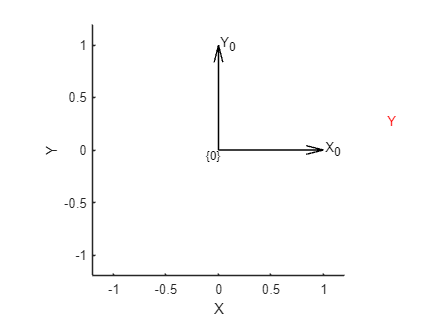

plottform2d(TC*TX,framelabel="XC",color="r");

#### 2.2.2.3 Matrix Exponential for Pose

L = logm(TC)

L =          0   -2.0000    4.0000
    2.0000         0   -6.0000
         0         0         0


S = skewa2vec(L)

S =     2.0000    4.0000   -6.0000


expm(vec2skewa(S))

ans =    -0.4161   -0.9093    6.0670
    0.9093   -0.4161    0.1044
         0         0    1.0000


X = vec2skewa([1 2 3])

X =      0    -1     2
     1     0     3
     0     0     0


skewa2vec(X)

ans =      1     2     3


#### 2.2.2.4 2D Twists

S = Twist2d.UnitRevolute(C)

 
S = 
( 1; 2  -3 )


expm(vec2skewa(2*S.compact))

ans =    -0.4161   -0.9093    6.0670
    0.9093   -0.4161    0.1044
         0         0    1.0000


S.tform(2)

ans =    -0.4161   -0.9093    6.0670
    0.9093   -0.4161    0.1044
         0         0    1.0000


S.pole

ans =      3     2


S = Twist2d.UnitPrismatic([0 1])

 
S = 
( 0; 0  1 )


S.tform(2)

ans =      1     0     0
     0     1     2
     0     0     1


T = trvec2tform([3 4])*tformr2d(0.5)

T =     0.8776   -0.4794    3.0000
    0.4794    0.8776    4.0000
         0         0    1.0000


S = Twist2d(T)

 
S = 
( 0.5; 3.9372  3.1663 )


S.w

ans = 0.5000

S.pole

ans =    -3.1663    3.9372


S.tform()

ans =     0.8776   -0.4794    3.0000
    0.4794    0.8776    4.0000
         0         0    1.0000


## 2.3 Working in Three Dimensions (3D)

### 2.3.1 Orientation in Three Dimensions

#### 2.3.1.1 3D Rotation Matrix

R = rotmx(pi/2)

R =      1     0     0
     0     0    -1
     0     1     0


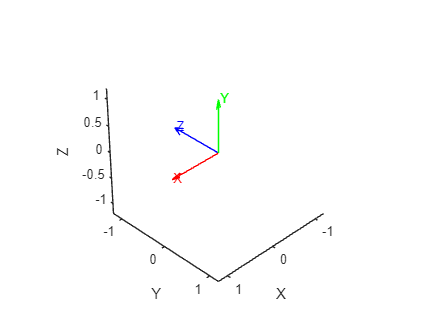

clf; plottform(R);

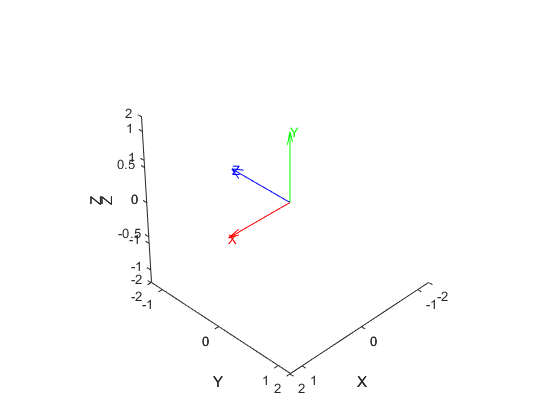

clf; animtform(R)
clf; plottform(R,anaglyph="rc", axis=[-2 2 -2 2 -2 2])

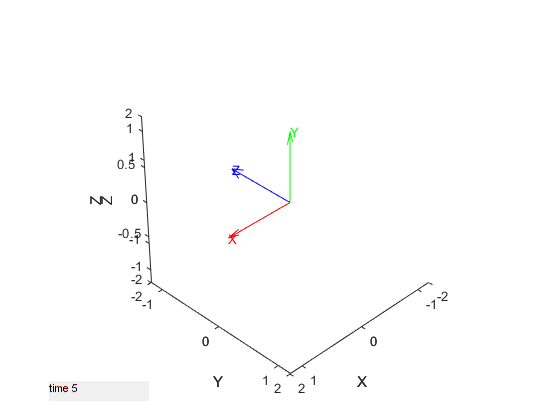

clf; animtform(R,anaglyph="rc", axis=[-2 2 -2 2 -2 2]);

R = rotmx(pi/2)*rotmy(pi/2)

R =      0     0     1
     1     0     0
     0     1     0


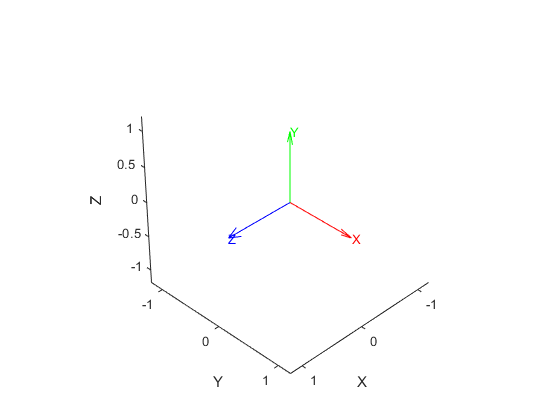

clf; plottform(R)

rotmy(pi/2)*rotmx(pi/2)

ans =      0     1     0
     0     0    -1
    -1     0     0


#### 2.3.1.2 Three-Angle Representations

R = rotmz(0.1)*rotmy(-0.2)*rotmz(0.3)

R =     0.9021   -0.3836   -0.1977
    0.3875    0.9216   -0.0198
    0.1898   -0.0587    0.9801


R = eul2rotm([0.1 -0.2 0.3],"ZYZ")

R =     0.9021   -0.3836   -0.1977
    0.3875    0.9216   -0.0198
    0.1898   -0.0587    0.9801


gamma = rotm2eul(R,"ZYZ")

gamma =     0.1000   -0.2000    0.3000


R = eul2rotm([0.1 0.2 0.3],"ZYZ")

R =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


gamma = rotm2eul(R,"ZYZ")

gamma =    -3.0416   -0.2000   -2.8416


eul2rotm(gamma,"ZYZ")

ans =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


R = eul2rotm([0.1 0 0.3],"ZYZ")

R =     0.9211   -0.3894         0
    0.3894    0.9211         0
         0         0    1.0000


rotm2eul(R,"ZYZ")

ans =          0         0    0.4000


R = eul2rotm([0.3 0.2 0.1],"ZYX")

R =     0.9363   -0.2751    0.2184
    0.2896    0.9564   -0.0370
   -0.1987    0.0978    0.9752


gamma = rotm2eul(R,"ZYX")

gamma =     0.3000    0.2000    0.1000


R = eul2rotm([0.3 0.2 0.1],"XYZ")

R =     0.9752   -0.0978    0.1987
    0.1538    0.9447   -0.2896
   -0.1593    0.3130    0.9363


gamma = rotm2eul(R,"XYZ")

gamma =     0.3000    0.2000    0.1000


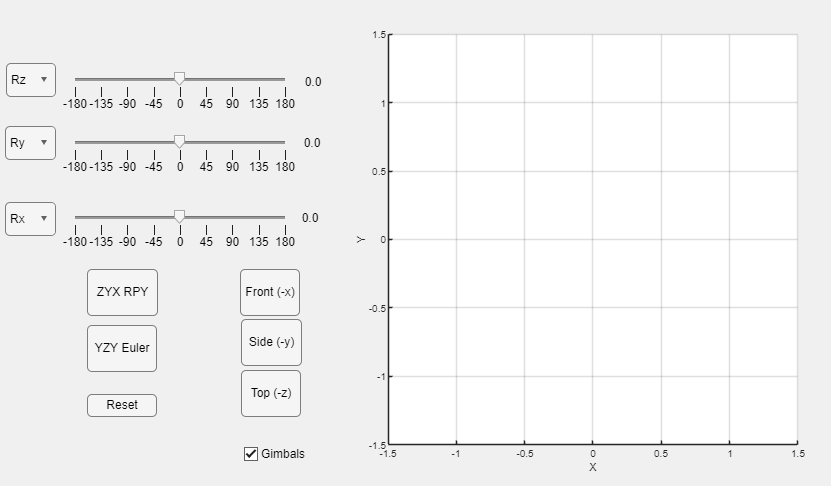

reading STL models...

错误使用 stlread
无法打开文件 'spitfire_assy-gear_up.stl'。

出错 tripleangleApp/tripleangle_OpeningFcn (第 125 行)
            tr = stlread( 'spitfire_assy-gear_up.stl');

出错 tripleangleApp>@(app)tripleangle_OpeningFcn(app,varargin{:}) (第 428 行)
          

tripleangleApp

#### 2.3.1.4 Two-Vector Representation

a = [0 0 -1];
o = [1 1 0];
R = oa2rotm(o,a)

#### 2.3.1.5 Rotation about an Arbitrary Vector

R = eul2rotm([0.1 0.2 0.3]);
rotm2axang(R)

ans =     0.7900    0.5834    0.1886    0.3655


[x,e] = eig(R)

x =   -0.7900 + 0.0000i  -0.1073 - 0.4200i  -0.1073 + 0.4200i
  -0.5834 + 0.0000i  -0.0792 + 0.5688i  -0.0792 - 0.5688i
  -0.1886 + 0.0000i   0.6944 + 0.0000i   0.6944 + 0.0000i


e =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.9339 + 0.3574i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.9339 - 0.3574i


theta = angle(e(2,2))

theta = 0.3655

R = axang2rotm([1 0 0 0.3])

R =     1.0000         0         0
         0    0.9553   -0.2955
         0    0.2955    0.9553


#### 2.3.1.6 Matrix Exponential for Rotation

R = rotmx(0.3)

R =     1.0000         0         0
         0    0.9553   -0.2955
         0    0.2955    0.9553


L = logm(R)

L =          0         0         0
         0         0   -0.3000
         0    0.3000         0


S = skew2vec(L)

S =     0.3000         0         0


expm(L)

ans =     1.0000         0         0
         0    0.9553   -0.2955
         0    0.2955    0.9553


expm(vec2skew(S))

ans =     1.0000         0         0
         0    0.9553   -0.2955
         0    0.2955    0.9553


R = rotmx(0.3);
R = expm(0.3*vec2skew([1 0 0]))

R =     1.0000         0         0
         0    0.9553   -0.2955
         0    0.2955    0.9553


X = vec2skew([1 2 3])

X =      0    -3     2
     3     0    -1
    -2     1     0


skew2vec(X)

ans =      1     2     3


#### 2.3.1.7 Unit Quaternions

q = quaternion(rotmx(0.3),"rotmat","point")

q = quaternion
     0.98877 + 0.14944i +       0j +       0k


q = q*q;
q.conj

ans = quaternion
     0.95534 - 0.29552i +       0j +       0k


q*q

ans = quaternion
     0.82534 + 0.56464i +       0j +       0k


q*q.conj()

ans = quaternion
     1 + 0i + 0j + 0k


q.rotmat("point")

ans =     1.0000         0         0
         0    0.8253   -0.5646
         0    0.5646    0.8253


q.compact()

ans =     0.9553    0.2955         0         0


q.rotatepoint([1 0 0])

ans =      1     0     0


### 2.3.2 Pose in Three Dimensions

#### 2.3.2.1 Homogeneous Transformation Matrix

T = trvec2tform([2 0 0])*tformrx(pi/2)*trvec2tform([0 1 0])

T =      1     0     0     2
     0     0    -1     0
     0     1     0     1
     0     0     0     1


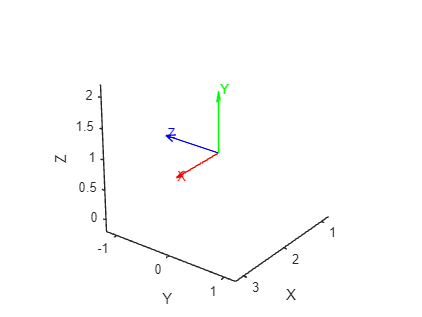

clf; plottform(T);

tform2rotm(T)

ans =      1     0     0
     0     0    -1
     0     1     0


tform2trvec(T)

ans =      2     0     1


#### 2.3.2.2 Matrix Exponential for Pose

T = trvec2tform([2 3 4])*tformrx(0.3)

T =     1.0000         0         0    2.0000
         0    0.9553   -0.2955    3.0000
         0    0.2955    0.9553    4.0000
         0         0         0    1.0000


L = logm(T)

L =          0         0         0    2.0000
         0         0   -0.3000    3.5775
         0    0.3000         0    3.5200
         0         0         0         0


S = skewa2vec(L)

S =     0.3000         0         0    2.0000    3.5775    3.5200


expm(vec2skewa(S))

ans =     1.0000         0         0    2.0000
         0    0.9553   -0.2955    3.0000
         0    0.2955    0.9553    4.0000
         0         0         0    1.0000


X = vec2skewa([1 2 3 4 5 6])

X =      0    -3     2     4
     3     0    -1     5
    -2     1     0     6
     0     0     0     0


skewa2vec(X)

ans =      1     2     3     4     5     6


#### 2.3.3.3 3D Twists

S = Twist.UnitRevolute([1 0 0],[0 0 0])
expm(0.3*S.skewa());
S.tform(0.3)
S = Twist.UnitRevolute([0 0 1], [2 3 2], 0.5);
X = trvec2tform([3 4 -4]);
clf; hold on
view(3)
for theta = [0:0.3:15]
  plottform(S.tform(theta)*X,style="rgb",labelstyle="none",LineWidth=2)
end
hold off
L = S.line();
L.plot("k:",LineWidth=2);
S = Twist.UnitPrismatic([0 1 0])
S.tform(2)
T = trvec2tform([1 2 3])*eul2tform([0.3 0.4 0.5]);
S = Twist(T)
S.w
S.pole
S.pitch
S.theta

## 2.4 Advanced Topics

### 2.4.5 Distance Between Orientations

q1 = quaternion(rotmx(pi/2),"rotmat","point");
q2 = quaternion(rotmz(-pi/2),"rotmat","point");
q1.dist(q2)

### 2.4.6 Normalization

R = eye(3);
det(R)-1
for i = 1:100
  R = R*eul2rotm([0.2 0.3 0.4]);
end
det(R) - 1
R = tformnorm(R);
det(R)-1
q = q.normalize();

### 2.4.8 More About Twists

S = Twist.UnitRevolute([1 0 0],[0 0 0])
S.compact()
S.v
S.w
S.skewa()
expm(0.3*S.skewa)
S.tform(0.3)
S2 = S*S
S2.printline(mode="axang", unit="rad")
line = S.line()
clf; axis([-2 2 -2 2 -2 2]); view(3); xlabel("x"); ylabel("y"); zlabel("z"); grid on
line.plot("k:",LineWidth=2);
T = trvec2tform([1 2 3])*eul2tform([0.3 0.4 0.5]);
S = Twist(T)
S/S.theta
S.unit();
S.tform(0)
S.tform(1)
S.tform(0.5)

## 2.5 MATLAB Classes for Pose and Rotation

T = trvec2tform([1 2 3])*tformrx(0.3)  % create SE(3) matrix as a MATLAB matrix
whos T
T = se3(rotmx(0.3),[1 2 3])  % create SE(3) matrix as an se3 object
whos T
T.tform()
whos ans
T.rotm()
T.trvec()
clf; plotTransforms(T,FrameLabel="A",FrameColor="b");
clf; plottform(T);
printtform(T);
P = [4 5 6];  % 3D point as a row vector
T.transform(P)
T.transform(P',IsCol=true)
T = rigidtform3d(rotmx(0.3),[1 2 3])  % create SE(3) matrix as a rigidtform3d object
whos T
T.A
T.R
T.Translation
T.transformPointsForward(P)
q = quaternion(rotmx(0.3),"rotmat","point")
conj(q)
q.conj()
q.conj

Suppress syntax warnings in this file

%#ok<*NOANS>
%#ok<*MINV>
%#ok<*NASGU>
%#ok<*NBRAK2>